# MATLAB SIMULATIONS AND RESULTS

## Design and analysis of circular cavity-backed antenna operating at 2.4 GHz 

### (20BEC130 and 21BEC508) 

#### Properties of Circular cavity are as follows:  

#### 1. Exciter: [1×1 dipole]  

#### 2. Substrate: [1×1 dielectric]

#### 3. Radius: 0.0375

#### 4. Height: 0.0264 

#### 5. Spacing: 0.0264  

#### 6. EnableProbeFeed: 0  

#### 7. Conductor: [1×1 metal]  

#### 8. Tilt: 0  

#### 9. TiltAxis: [1 0 0]  

#### 10. Load: [1×1 lumpedElement]

a=cavityCircular

a =   cavityCircular with properties:

            Exciter: [1×1 dipole]
          Substrate: [1×1 dielectric]
             Radius: 0.1000
             Height: 0.0750
            Spacing: 0.0750
    EnableProbeFeed: 0
          Conductor: [1×1 metal]
               Tilt: 0
           TiltAxis: [1 0 0]
               Load: [1×1 lumpedElement]


a=cavityCircular    

a =   cavityCircular with properties:

            Exciter: [1×1 dipole]
          Substrate: [1×1 dielectric]
             Radius: 0.1000
             Height: 0.0750
            Spacing: 0.0750
    EnableProbeFeed: 0
          Conductor: [1×1 metal]
               Tilt: 0
           TiltAxis: [1 0 0]
               Load: [1×1 lumpedElement]


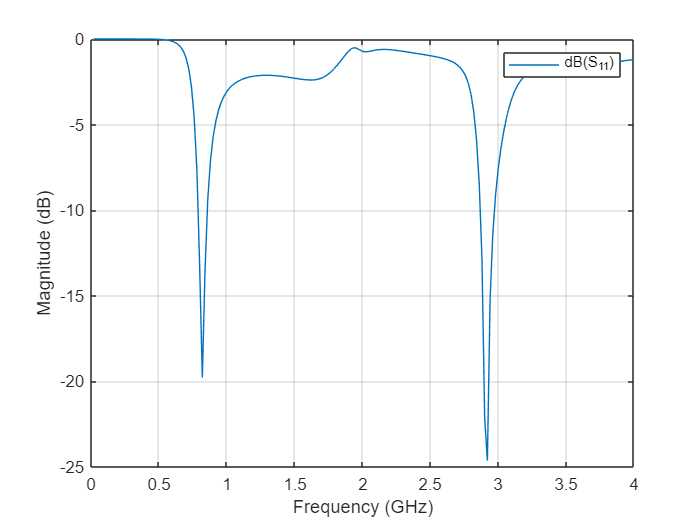

s=sparameters(a,20e6:20e6:4e9,50);
rfplot(s);

ant=design(a,2.4e9)

ant =   cavityCircular with properties:

            Exciter: [1×1 dipole]
          Substrate: [1×1 dielectric]
             Radius: 0.0375
             Height: 0.0264
            Spacing: 0.0264
    EnableProbeFeed: 0
          Conductor: [1×1 metal]
               Tilt: 0
           TiltAxis: [1 0 0]
               Load: [1×1 lumpedElement]


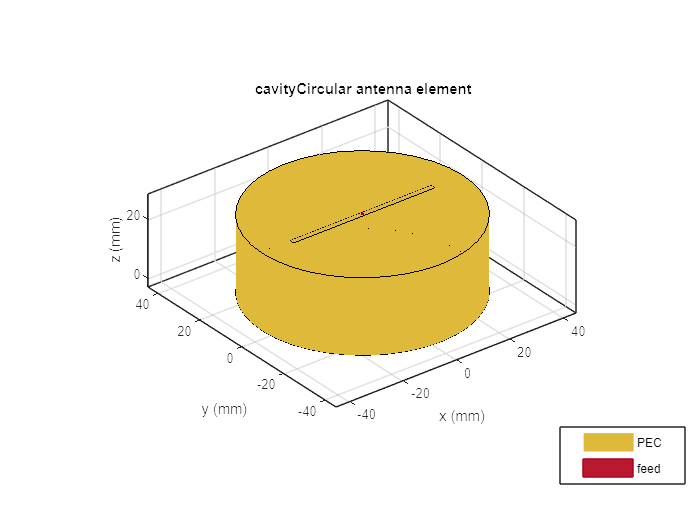

show(ant) 

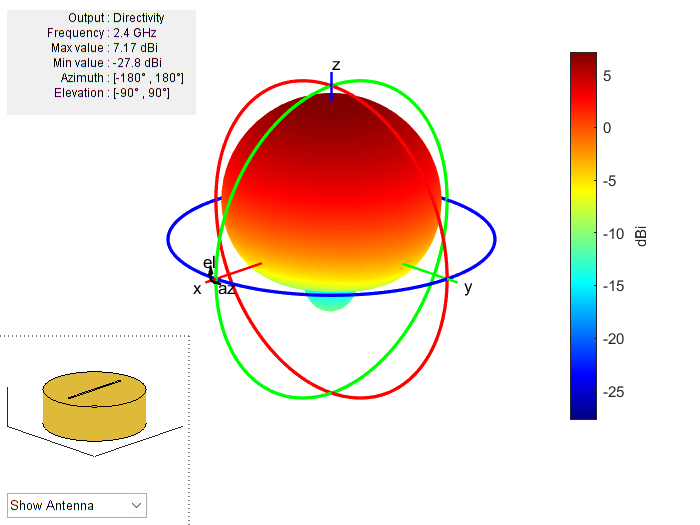

pattern(ant,2.4e9)

**Radiation Pattern**

It can be observed that maximum value of directivity is  7.17dB indicated by red colour and minimum value of  directivity is -27.8dB indicated by blue colour. 

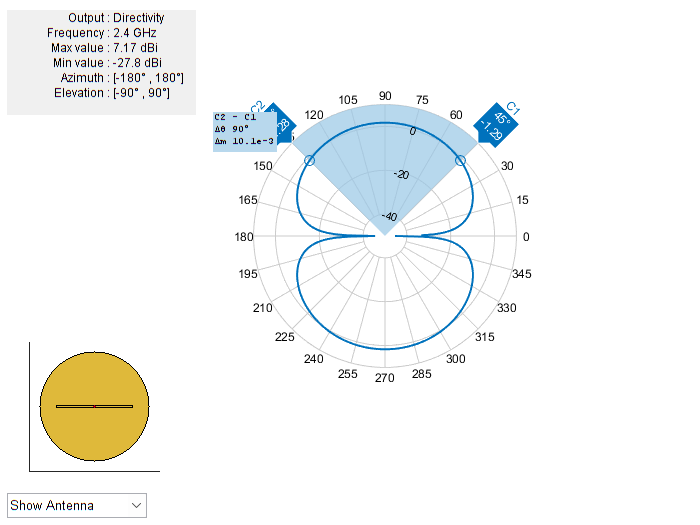

beamwidth(a,2.4e6,0,1:1:360)

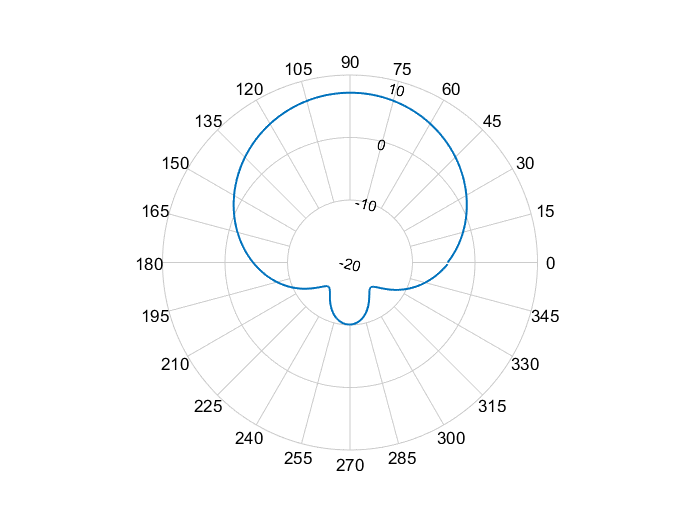

pattern(ant,2.4e9,0,0:1:360)
p2=pattern(ant,2.4e9,0:1:360,0);
p22=polarpattern(p2);
p1=pattern(ant,2.4e9,0,0:1:360);
p11=polarpattern(p1);

L1=findLobes(p11)

L1 = struct with fields:
     mainLobe: [1×1 struct]
     backLobe: [1×1 struct]
    sideLobes: [1×1 struct]
           FB: 17.2404
          SLL: 17.2382
         HPBW: 85.7618
         FNBW: 278.2271
        FBIdx: [91 271.5000]
       SLLIdx: [91 271]
      HPBWIdx: [48 134]
      HPBWAng: [46.8698 132.6316]
      FNBWIdx: [312 230]


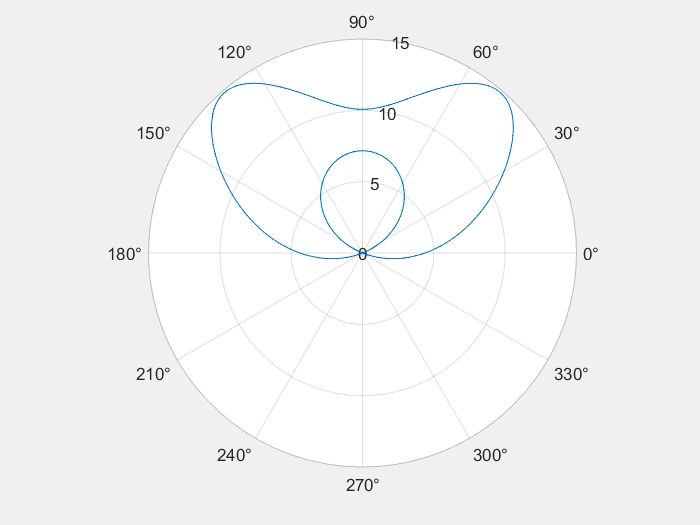

polarplot(p1)

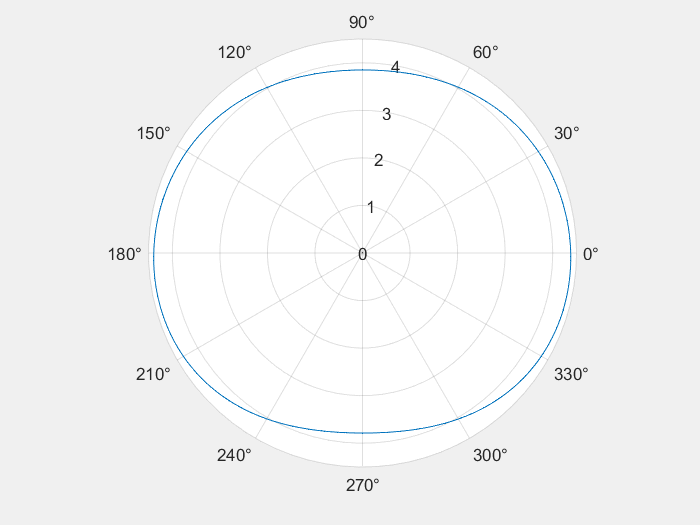

polarplot(p2)

L1=findLobes(p11)

L1 = struct with fields:
     mainLobe: [1×1 struct]
     backLobe: [1×1 struct]
    sideLobes: [1×1 struct]
           FB: 17.2404
          SLL: 17.2382
         HPBW: 85.7618
         FNBW: 278.2271
        FBIdx: [91 271.5000]
       SLLIdx: [91 271]
      HPBWIdx: [48 134]
      HPBWAng: [46.8698 132.6316]
      FNBWIdx: [312 230]


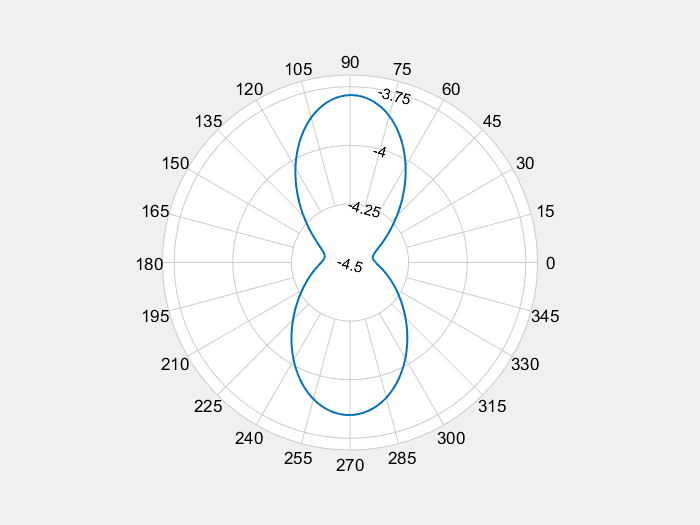

p2=pattern(ant,2.4e9,0:1:360,0);
p22=polarpattern(p2);

s=sparameters(ant,20e6:20e6:4e9,50)

s =   sparameters: S-parameters object

       NumPorts: 1
    Frequencies: [200×1 double]
     Parameters: [1×1×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


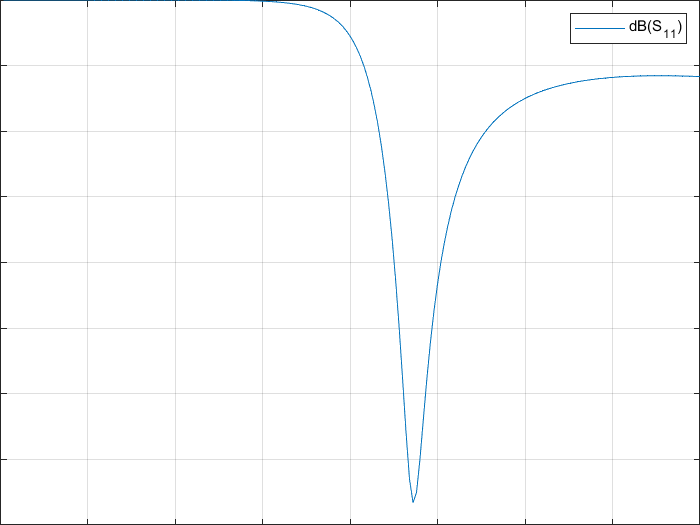

rfplot(s);

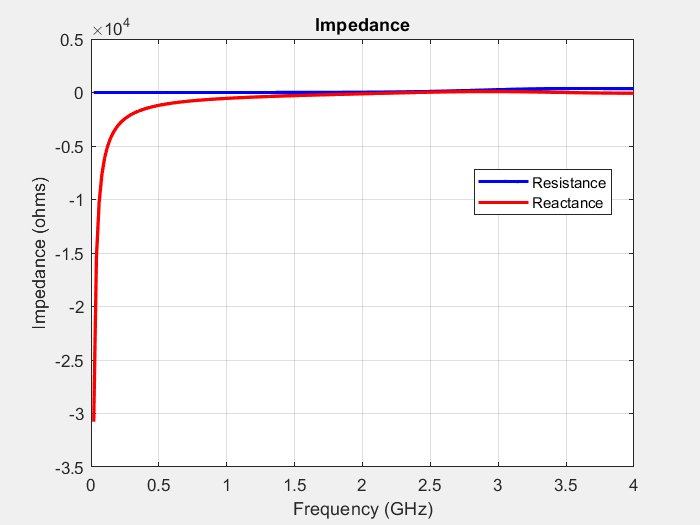

impedance(ant,20e6:20e6:4e9);

impedance1=impedance(ant,2.4e9)

impedance1 = 73.6128 - 0.0094i

**Impedance**

Reactance at operating frequency (2.4GHz) is close to 0 as wave must resonate at operating  frequency (Xl=Xc).  

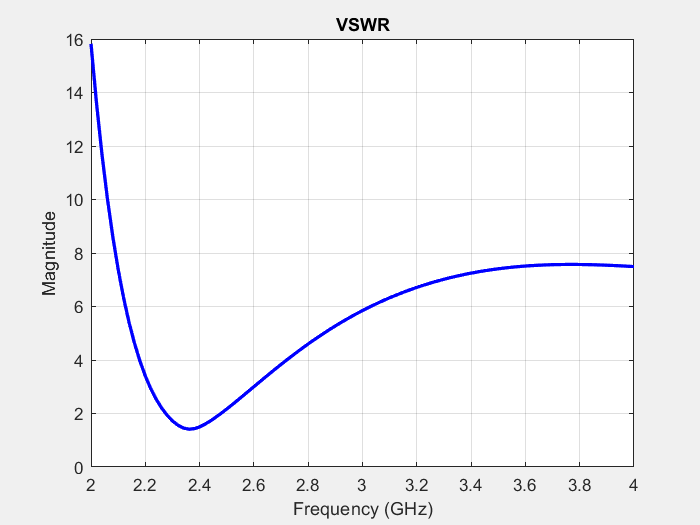

vswr(ant,2e9:20e6:4e9,50)

**VSWR**

VSWR value is 1.47 at operating frequency. Ideally it  should be less than 2, Thus the performance is good. 

vswr1=vswr(ant,2.4e9)

vswr1 = 1.4723

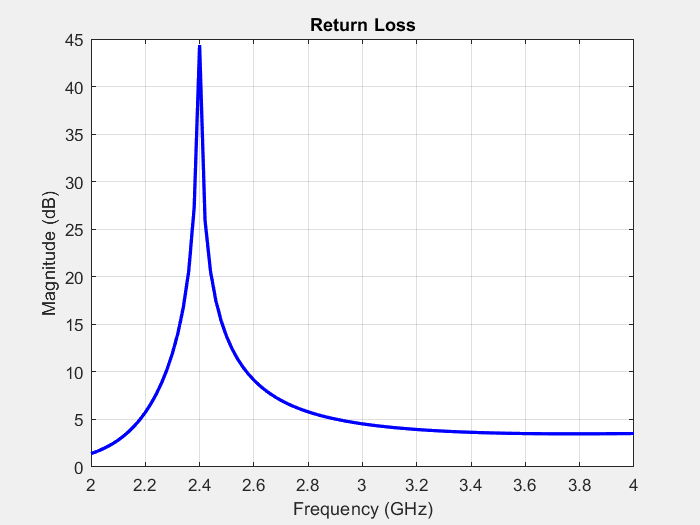

returnLoss(ant,2e9:20e6:4e9,75)

rL1=returnLoss(ant,2.4e9)

rL1 = 14.3783

**Return Loss**

Return loss specifies how small the return  or reflection is. So, for a small return, large loss of the  returned signal is desired. Here, the antenna has  maximum return loss at operating frequency hence we can  see a peak at 2.4 GHz. 

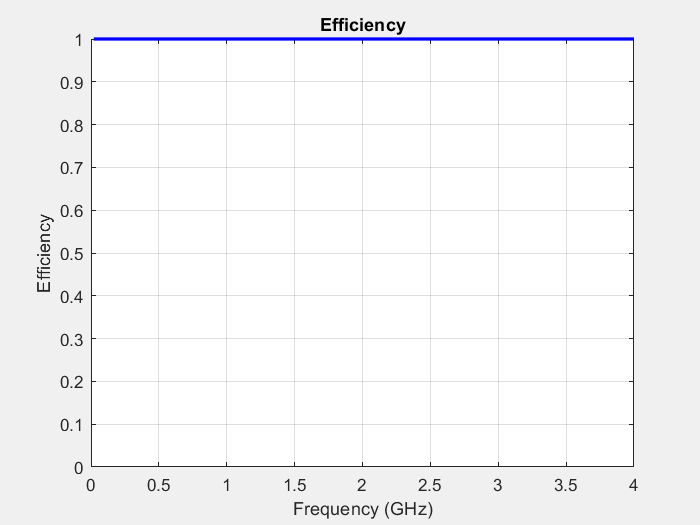

efficiency(ant,linspace(20e6,4e9,100))

efficiency1=efficiency(ant,2.4e9)

efficiency1 = 1

hpbw_el=[46.8698 132.6361];
hpbw_az=[0 359.0028];
hpbw=[hpbw_az;hpbw_el]

hpbw =          0  359.0028
   46.8698  132.6361


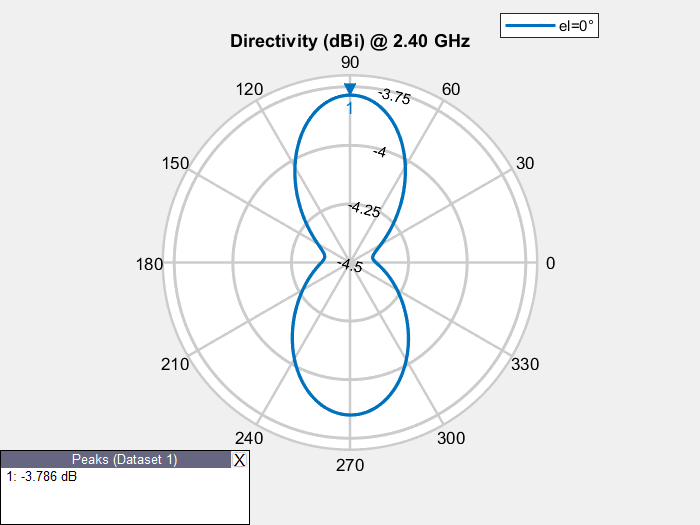

patternAzimuth(ant,2.4e9)

**Directivity**

For AZ=0, Maximum directivity is 7.168dB and is observed at 90 degree.

For el=0, Maximum directivity is -3.789dB and is observed at 90 degree.

patternElevation(ant,2.4e9)
[bw, angles]=beamwidth(ant,2.4e9,0,0:1:360)

bw = 86

angles =     47   133


[bw, angles]=beamwidth(ant,2.4e9,0,0:1:360)

bw = 86

angles =     47   133


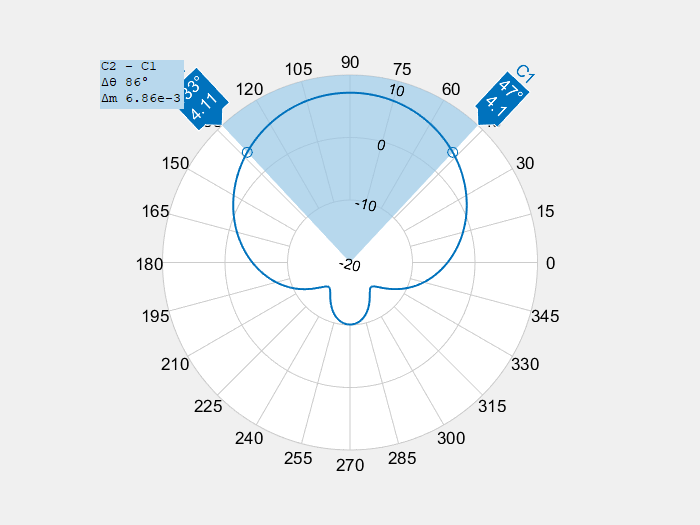

beamwidth(ant,2.4e9,0,0:1:360)

**Beamwidth** 

It is observed that beamwidth is 90 degrees, and for  maximum power radiation, receptor has to be placed  in the 45-to-135-degree slot.  

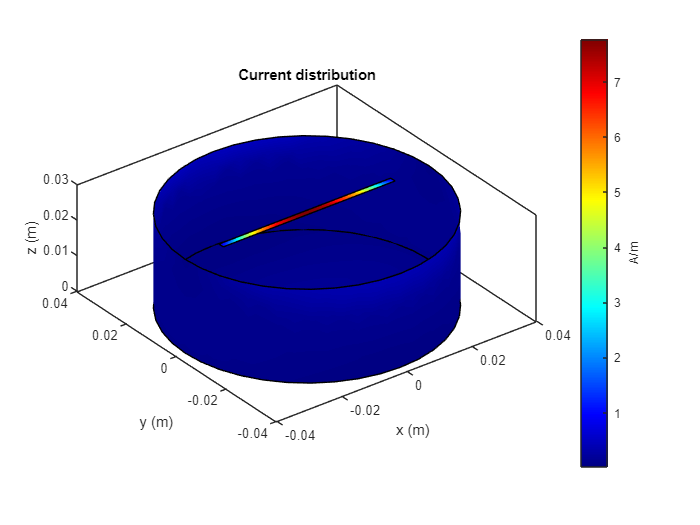

figure
current(ant,2.4e9)

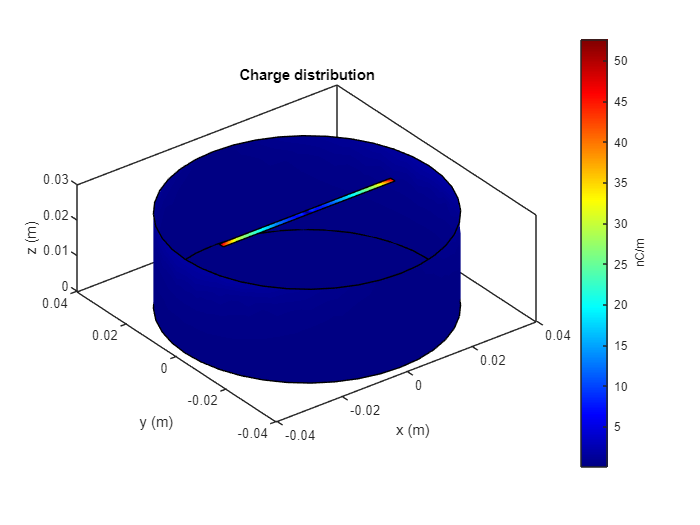

charge(ant,2.4e9)

**Current Distribution**

Almost uniform current distribution of around 1A across the antenna and can be observed except for  the rectangular patch.

Z = impedance(ant,2.4e9)

Z = 73.6128 - 0.0094i

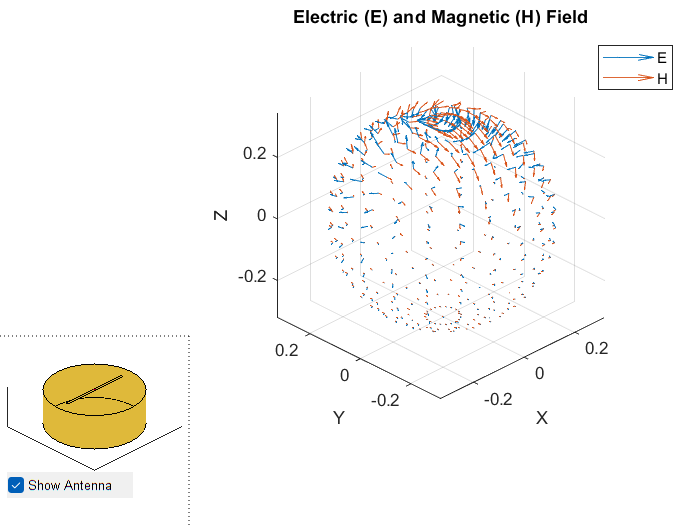

EHfields(a,2.4e6)